# HRI Lab #7, SP2024 525.786: Human Robotics Interaction

## Introduction:

In this lab we will explore interfacing various types of motion tracking tools. These tools, in combination with the bioinstrumentation inputs you've used previously, can be used for natural and intuitive Human Robotic Interaction. The tools that we'll be using include the following devices:

## Setup the MiniVIE environment

thisPath = cd;
cd('C:\GitHub\MiniVIE');
MiniVIE.configurePath;

[MiniVIE.m] Configured MiniVIE path at: C:\GitHub\minivie


cd(thisPath);

## Part 1: Inertial Measurement Unit on the Myo

Operating Principle: the Myo armband contains an Angular rate sensor, accelerometer, and magnetometer to resolve orientation.  These sensors can be used to track motion of the arm in addition to the EMG signals

Before running the code below, be sure to start MyoUdp.exe in the MiniVIE/+Inputs folder

It might be more straightforward to run this in the Command Window (select, then hit F9)

% Setup the Myo Armband in matlab
hMyo = Inputs.MyoUdp.getInstance();

[MyoUdp] Calling constructor


hMyo.initialize()

[UserConfig.m] Calling constructor with config file C:\GitHub\minivie\user_config.xml
[UserConfig.m] myoUdpRate=200
[UserConfig.m] myoUdpPort1=10001
[UserConfig.m] myoUdpPort2=10002

Loaded pnet Version  2.0.5  2003-09-16 Copyright (C) Peter Rydesäter, Sweden, et al. , 1998 - 2003
[PnetClass] Opened pnet socket #0 at local port: 10001; Default destination: port 45001 @ 127.0.0.1
[PnetClass] Opened pnet socket #1 at local port: 10002; Default destination: port 45001 @ 127.0.0.1
[MyoUdp] UDP Data Stream 1-8 NOT Detected
[MyoUdp] UDP Data Stream 9-16 NOT Detected


ans = 0

pause(1)

% Ensure data is streaming
myoData = hMyo.getData();
if isempty(hMyo.Orientation)
    error('Setup Failed.  MyoUdp Running?');
end

% Setup figure to show orientation
figure(1);
clf
daspect([1 1 1])
view(-170,15)

% Plot reference triad
PlotUtils.triad(eye(4),0.5)

ans = 10.0009

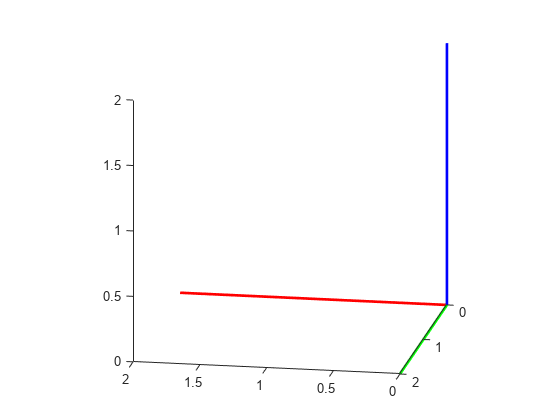

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
     0
     0

     0
   


% Plot 'moving' triad
myoTriadHandle = PlotUtils.triad(eye(4),2);
StartStopForm([])
while StartStopForm()
    drawnow
    hMyo.getData();  % update stream receive
    Rxyz = hMyo.getEulerAngles; % Get roll pitch yaw
    disp(Rxyz)
    Rmat = LinAlg.makeRotationMtx(Rxyz); % create rotation matrix
    transMat = [Rmat [0; 0; 0]; 0 0 0 1];
    set(myoTriadHandle,'Matrix', transMat);    
end

hMyo.close()

[MyoUdp] Deleting Udp comms object
[PnetClass.m] Closed pnet socket #0 at local port: 10001
[PnetClass.m] Closed pnet socket #1 at local port: 10002



cleanup;


Loaded pnet Version  2.0.5  2003-09-16 Copyright (C) Peter Rydesäter, Sweden, et al. , 1998 - 2003


cleanup
---------------------------------------
---------------------------------------
---------------------------------------


**Questions:**

- What is the 'global' position of the myo armband?

The global position is [0 0 0] with a orientation of [0 0 0]

- What is its local coordinate frame?

The position of the local coordinate frame is the same as the global, but the orientation moves with the orientation of the myoband

- What processing would you do to use the myo armband as a sensor to control the elbow flexion angle of a robotic device?

You would have to map the flexion of the elbow to the myoband sensor input for the angle of movement in reference to the global frame so that the orientation of the myoband maps to the orientation of the end effector on the elbow

## Use the Myo Orientation Sensors to Plot Arm Position

Edit the code below to show (in a streaming fashion) the real-time orientation and position of the forearm.

It might be more straightforward to run this in the Command Window (select, then hit F9)

hMyo = Inputs.MyoUdp.getInstance();
hMyo.initialize()
pause(1)

% Ensure data is streaming
myoData = hMyo.getData();
if isempty(hMyo.Orientation)
    error('Setup Failed.  MyoUdp Running?');
end

% Can you create a real time plot of your hand's position in space using
% the real-time orientation matrix from the Myo?  assume the distance from
% Myo to hand is 25 cm.
myoOrigin = [0, 0, 0];
handPosStart = [0.25, 0, 0]; % in meters
figHandle = figure(1);
clf
daspect([1 1 1])
view(-170,15)

StartStopForm([])
while StartStopForm()    
    

    hMyo.getData();  
    Rxyz = hMyo.getEulerAngles;
    Rmat = LinAlg.makeRotationMtx(Rxyz);
    disp(Rmat)

    handPos = handPosStart * Rmat;
    
    
    plot3([0, handPos(1)], [0, handPos(2)], [0, handPos(3)], '.-');
    set(gca, 'XLim', [-0.25 0.25], 'YLim', [-0.25 0.25], 'ZLim', [-0.25 0.25]);
    xlabel('x'); ylabel('y'); zlabel('z');
    drawnow;
    
end
hMyo.close()
cleanup;

## Part 2: Kinect

Open "SDK Browser for Kinect" (search in Windows Start Menu)

Run the following examples:

- Audio Basics

- Depth Basics 

- Face Tracking Basics 

- Skeletal Basics

**Copy and paste window screenshots from each:**

- **Audio Basic**

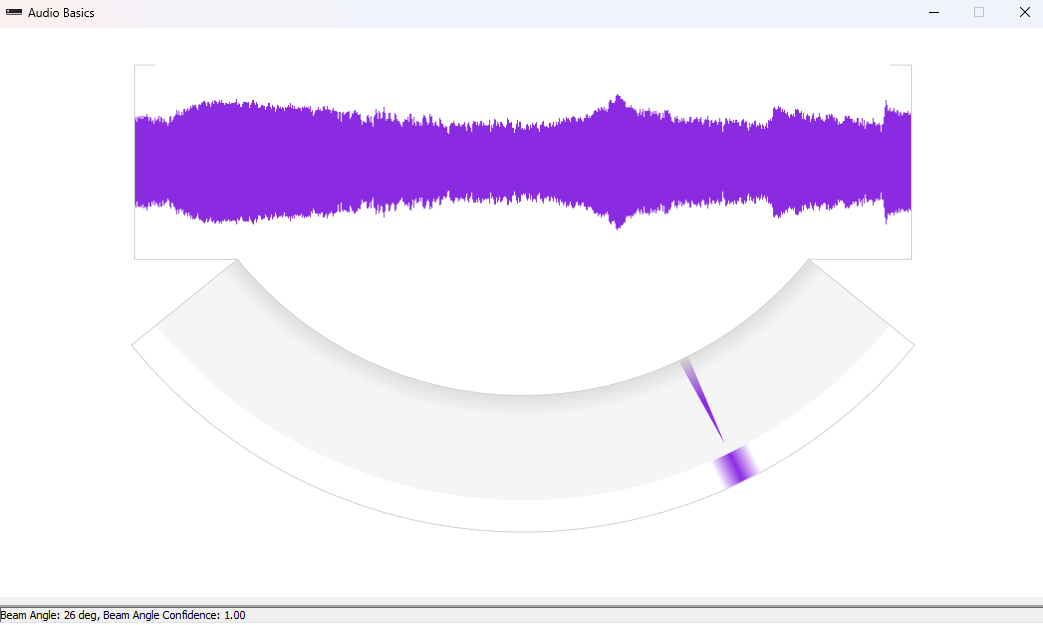

2. Depth Basic

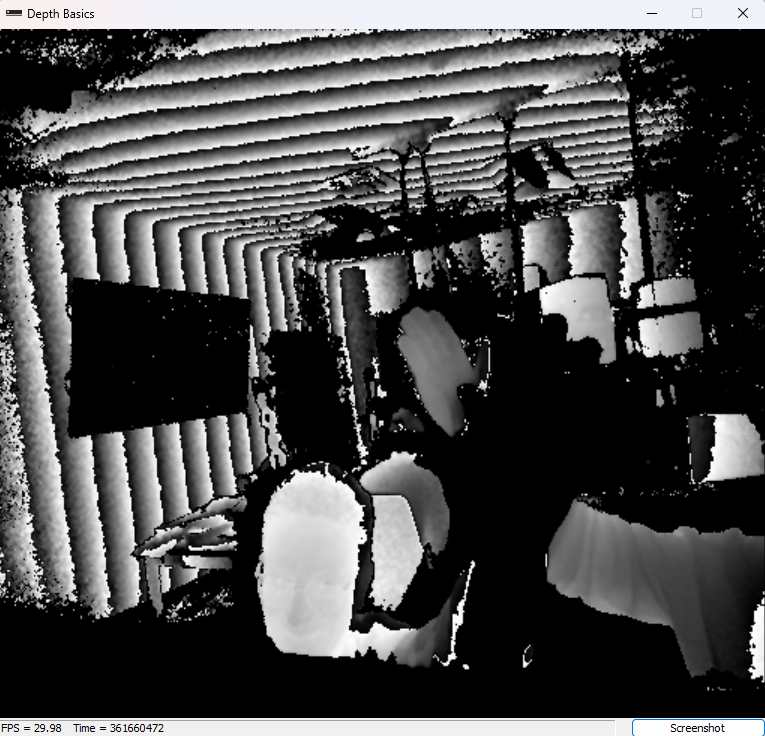

3. Face Tracking Basic

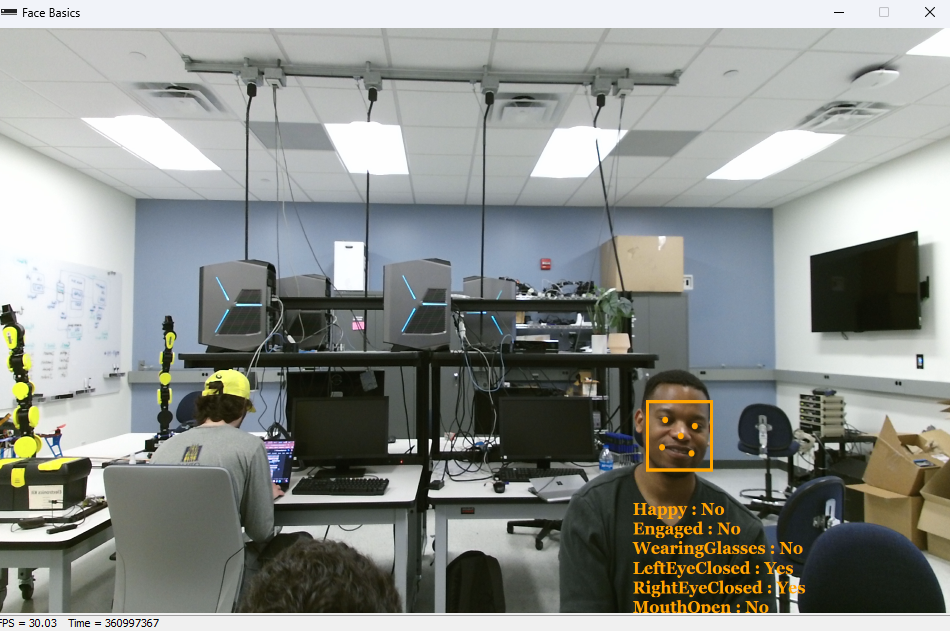

4. Skeletal Basic

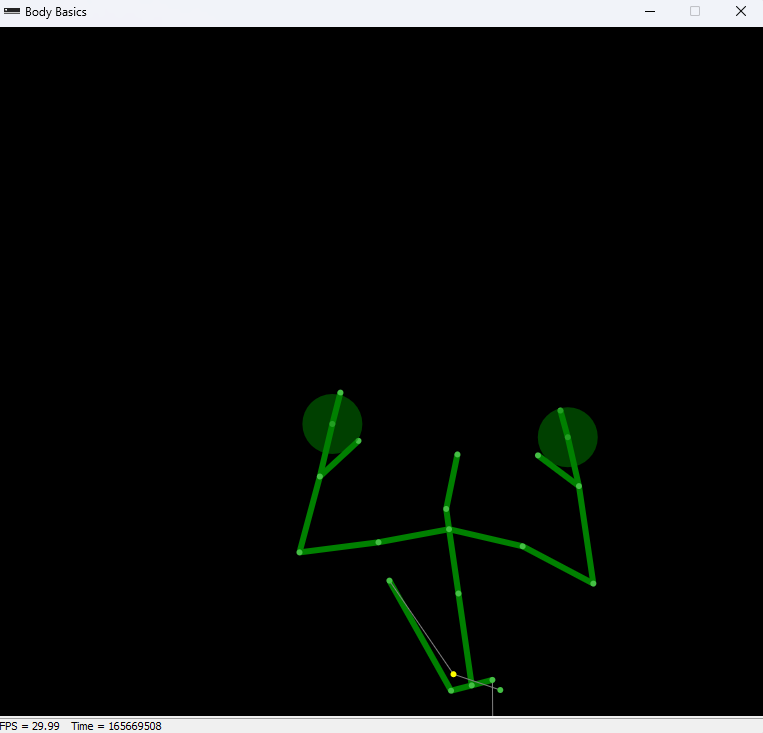

Questions:

- What advantage do microphone arrays have over traditional microphones / speech input devices? 

**It allows you to estimate the location of the noise with triangulation and it can better filter out noise. **

- At what range is the face tracking effective? How might this be used as a robot controller? 

**It works at approximately 1-3 yards from the kinnect.**

- What kind of motions and postures does the skeletal model capture?  When does it break down? 

The skeletal model captures the spine/core, upper leg, arm and hand position such as wether the fist is clenched, but not individual finger movements.

## Kinect sampling from MATLAB

derived from: [https://www.mathworks.com/help/imaq/examples/using-the-kinect-r-for-windows-r-from-image-acquisition-toolbox-tm.html](https://www.mathworks.com/help/imaq/examples/using-the-kinect-r-for-windows-r-from-image-acquisition-toolbox-tm.html)

required MATLAB Support Package for Kinect: [https://www.mathworks.com/hardware-support/kinect-windows.html](https://www.mathworks.com/hardware-support/kinect-windows.html)

It might be more straightforward to run this in the Command Window (select, then hit F9)

utilpath = 'C:\ProgramData\MATLAB\SupportPackages\R2019b\toolbox\imaq\supportpackages\kinectruntime\kinectforwindowsruntimeexamples';
addpath(utilpath);

% The Kinect for Windows Sensor shows up as two separate devices in IMAQHWINFO.
hwInfo = imaqhwinfo('kinect')
hwInfo.DeviceInfo(1)
hwInfo.DeviceInfo(2)

% Create the VIDEOINPUT objects for the two streams
colorVid = videoinput('kinect',1)
depthVid = videoinput('kinect',2)

% Set the triggering mode to 'manual'
triggerconfig([colorVid depthVid],'manual');
colorVid.FramesPerTrigger = 100;
depthVid.FramesPerTrigger = 100;

% Start the color and depth device. This begins acquisition, but does not
% start logging of acquired data.
start([colorVid depthVid]);

% Trigger the devices to start logging of data.
trigger([colorVid depthVid]);

% Retrieve the acquired data
[colorFrameData,colorTimeData,colorMetaData] = getdata(colorVid);
[depthFrameData,depthTimeData,depthMetaData] = getdata(depthVid);

% Stop the devices
stop([colorVid depthVid]);

% display one of the frames
figure(1);
subplot(2, 1, 1);
imagesc(colorFrameData(:, :, :, 50));axis equal tight;
subplot(2, 1, 2);
imagesc(depthFrameData(:, :, :, 50)); axis equal tight;

**Copy and the screenshots of your RGB and depth maps:**

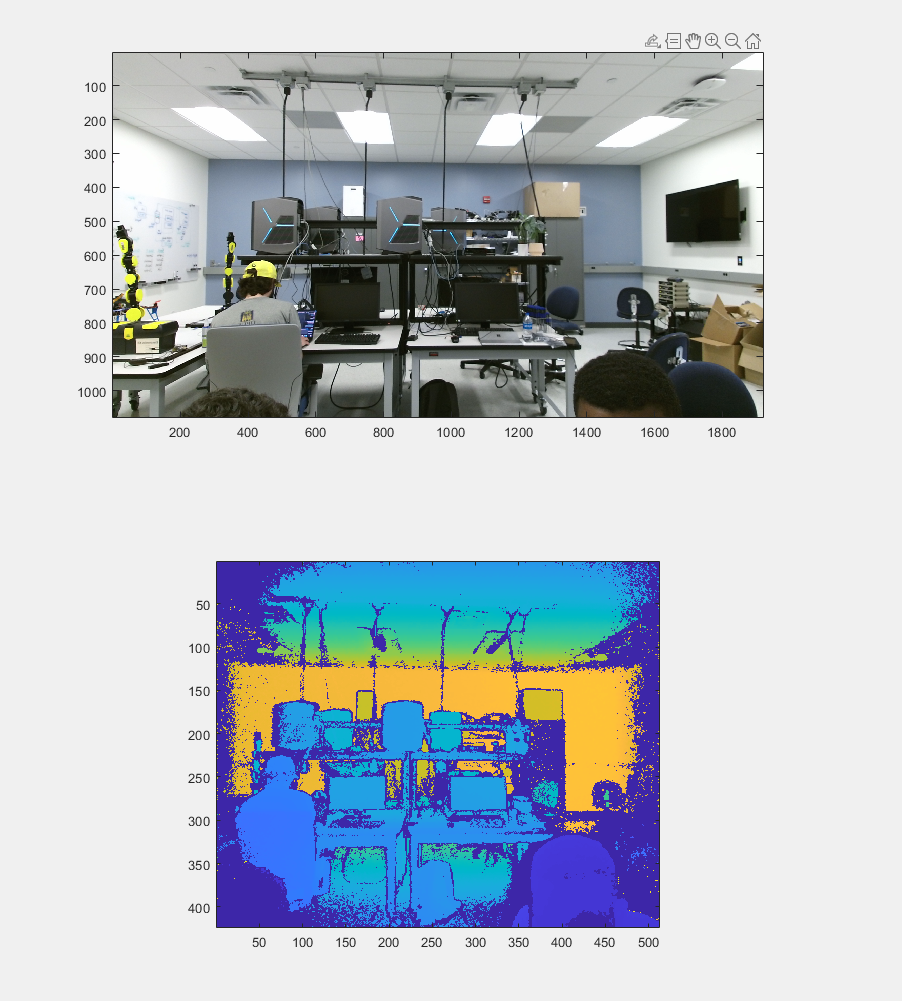

## Skeletal tracking

Grab a frame including a person's body (i.e., "skeleton" in Kinect terms)

depthSrc = getselectedsource(depthVid)

depthSrc =    Display Summary for Video Source Object:

      General Settings:
        Parent = [1x1 videoinput]
        Selected = on
        SourceName = Kinect V2 Depth Source
        Tag = [0x0 string]
        Type = videosource

      Device Specific Properties:
        EnableBodyTracking = off



% Turn on skeletal tracking.
depthSrc.EnableBodyTracking = 'on';

% Acquire 100 frames with tracking turned on.
% Remember to have a person in person in front of the
% Kinect for Windows to see valid tracking data.
colorVid.FramesPerTrigger = 100;
depthVid.FramesPerTrigger = 100;

start([colorVid depthVid]);
trigger([colorVid depthVid]);

% Retrieve the frames and check if any Skeletons are tracked
[frameDataColor] = getdata(colorVid);
[frameDataDepth, timeDataDepth, metaDataDepth] = getdata(depthVid);

% View skeletal data from depth metadata
metaDataDepth

metaDataDepth = 100×1 struct array with fields:
    AbsTime
    BodyIndexFrame
    BodyTrackingID
    ColorJointIndices
    DepthJointIndices
    FrameNumber
    HandLeftConfidence
    HandLeftState
    HandRightConfidence
    HandRightState
    IsBodyTracked
    JointPositions
    JointTrackingState
    RelativeFrame
    TriggerIndex



% Check for tracked skeletons from depth metadata
anyBodiesTracked = any(metaDataDepth(95).IsBodyTracked ~= 0)

anyBodiesTracked = logical
   1



% See which skeletons were tracked.
trackedBodies = find(metaDataDepth(95).IsBodyTracked)

trackedBodies = 1


jointCoordinates = metaDataDepth(95).JointPositions(:, :, trackedBodies)

jointCoordinates =     0.2430   -0.7548    1.4857
    0.2547   -0.5556    1.5198
    0.2647   -0.3579    1.5445
    0.2651   -0.2669    1.5464
    0.0936   -0.4471    1.5462
    0.0542   -0.6110    1.4932
    0.0575   -0.7436    1.3959
    0.0466   -0.7704    1.3789
    0.4159   -0.4343    1.4651
    0.4413   -0.5948    1.3940


% Skeleton's joint indices with respect to the color image
jointIndices = metaDataDepth(95).ColorJointIndices(:, :, trackedBodies)

jointIndices = 1.0e+03 *

    1.1765    1.1019
    1.1792    0.9451
    1.1819    0.7987
    1.1816    0.7342
    1.0613    0.8617
    1.0368    0.9933
    1.0454    1.1294
    1.0380    1.1582
    1.3074    0.8692
    1.3460    1.0121



% Pull out the 95th color frame
image = frameDataColor(:, :, :, 95);

% Find number of Skeletons tracked
nBodies = length(trackedBodies);

Now plot the skeleton over the RGB image

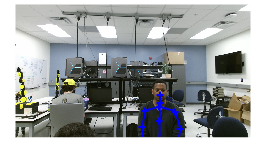

% Create skeleton connection map to link the joints.
SkeletonConnectionMap = [ [4 3];  % Neck
                          [3 21]; % Head
                          [21 2]; % Right Leg
                          [2 1];  
                          [21 9];
                          [9 10];  % Hip
                          [10 11];
                          [11 12]; % Left Leg
                          [12 24];
                          [12 25];
                          [21 5];  % Spine
                          [5 6];
                          [6 7];   % Left Hand 
                          [7 8];    
                          [8 22];
                          [8 23];
                          [1 17];
                          [17 18];
                          [18 19];  % Right Hand
                          [19 20];
                          [1 13];
                          [13 14];
                          [14 15];
                          [15 16];                          
                        ];

% Marker colors for up to 6 bodies.
colors = ['b';'r';'g';'c';'y';'m'];

% Display the RGB image.
imshow(image);

% Overlay the skeleton on this RGB frame.
for i = 1:24
     for body = 1:nBodies
         X1 = [jointIndices(SkeletonConnectionMap(i,1),1,body) jointIndices(SkeletonConnectionMap(i,2),1,body)];
         Y1 = [jointIndices(SkeletonConnectionMap(i,1),2,body) jointIndices(SkeletonConnectionMap(i,2),2,body)];
         line(X1,Y1, 'LineWidth', 1.5, 'LineStyle', '-', 'Marker', '+', 'Color', colors(body));
     end
     
    hold on;
 end
 hold off;

**Copy and paste a screenshot overlaid with the extracted skeleton:**

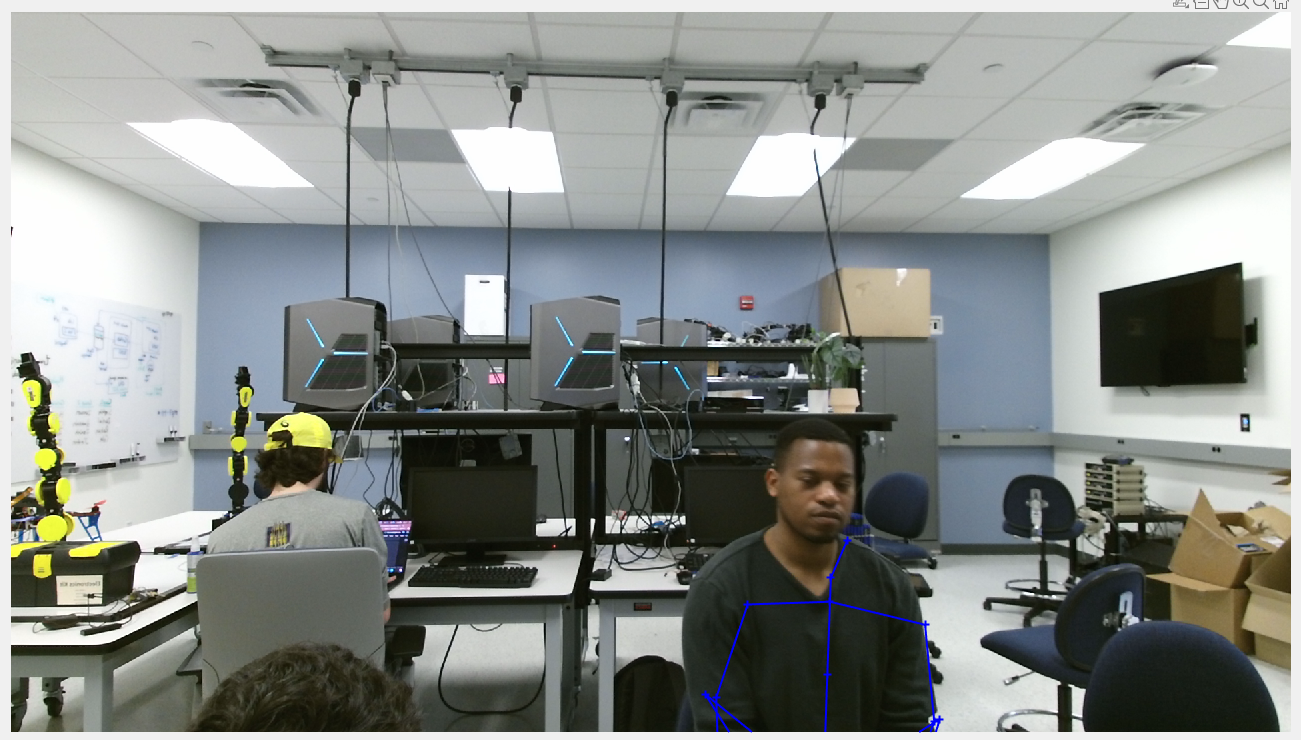

Tasks/Questions:

- Did the skeleton model accurately capture your body geometry? 

Fairly accurately, but it's a little off. The right arm skeleton was not centered on the arm and the neck was off to the side, but the core and one arm was fairly close.

- How would you estimate the elbow angle from the skeletal model? 

You could estimate it by taking the angle between the upper arm and lower arm lines.

## **Submitting This Lab**

Export this *.mlx file as Lab7_##_<LastName1>_<LastName2>_<LastName3>_<LastName4>.pdf (## should be your computer number) and email to Lauren.Diaz@jhuapl.edu